close all, clear all
% A1 Uni(80,120)
% A2 Uni(65,140)
% A3 Norm(120,40)
% A4 Norm(100,15)
% A5 Lnorm(4.8,0.7)
% A6 Lnorm(4.5,0.9)
% A7 Exp(100)
% A8 Exp(125)
% A9 Weib(105,2)
% A10 Weib(130,3)

% a %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%fill the parts XXXXXXX
t = 0:0.5:200;
pd1 = makedist('Uniform','lower',80,'upper',120);
a1 = pdf(pd1,t);
pd2 = makedist('Uniform','lower',65,'upper',140);
a2 = pdf(pd2,t);
pd3 = makedist('Normal','mu',120,'sigma',40);
a3 = pdf(pd3,t);
pd4 = makedist('Normal','mu',100,'sigma',15);
a4 = pdf(pd4,t);
pd5 = makedist('Lognormal','mu',4.8,'sigma',0.7);
a5 = pdf(pd5,t);
pd6 = makedist('Lognormal','mu',4.5,'sigma',0.9);
a6 = pdf(pd6,t);
pd7 = makedist('Exponential','mu',100);
a7 = pdf(pd7,t);
pd8 = makedist('Exponential','mu',125);
a8 = pdf(pd8,t);
pd9 = makedist('Weibull','a',105,'b',2);
a9 = pdf(pd9,t);
pd10 = makedist('Weibull','a',130,'b',3);
a10 = pdf(pd10,t);


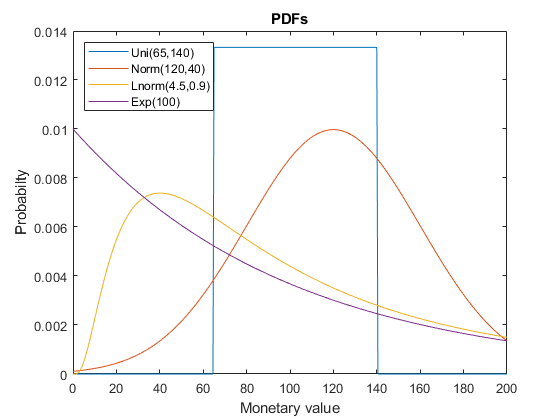


% b %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%create the plot of PDFs
%type 'help pdf' to see what the values a1,...,a10 are and if they can be
%used for plotting
plot(t,a2)
hold on
plot(t,a3)
plot(t,a6)
plot(t,a7)
xlabel('Monetary value')
ylabel('Probabilty')
title('PDFs')
legend('Uni(65,140)', 'Norm(120,40)', 'Lnorm(4.5,0.9)',"Exp(100)", 'location','northwest')


% c %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%create samples
samples =zeros(10,5000);
samples(1,:) = random(pd1,1,5000);
samples(2,:) = random(pd2,1,5000);
samples(3,:) = random(pd3,1,5000);
samples(4,:) = random(pd4,1,5000);
samples(5,:) = random(pd5,1,5000);
samples(6,:) = random(pd6,1,5000);
samples(7,:) = random(pd7,1,5000);
samples(8,:) = random(pd8,1,5000);
samples(9,:) = random(pd9,1,5000);
samples(10,:) = random(pd10,1,5000);


%vectors to save the results
EV = zeros(10,1);
Var1 = zeros(10,1);
Var5 = zeros(10,1);
Var10 = zeros(10,1);
CVar1 = zeros(10,1);
CVar5 = zeros(10,1);
CVar10 = zeros(10,1);

%calculate the results, some basic idea provided here
%look at slide 10 from lecture 4
%the for loop handles the 10 investment opportunities one at a time
for i = 1:10
    %EV
    EV(i) = mean(samples(i,:));
    %VaRs
    Var1(i) = prctile(samples(i,:), 1);
    Var5(i) = prctile(samples(i,:), 5);
    Var10(i) = prctile(samples(i,:), 10);
    %CVaRs
    TailIndices1 = find(samples(i,:)<Var1(i));
    CVar1(i) = mean(samples(TailIndices1));
    TailIndices5 = find(samples(i,:)<Var5(i));
    CVar5(i) = mean(samples(TailIndices5));
    TailIndices10 = find(samples(i,:)<Var10(i));
    CVar10(i) = mean(samples(TailIndices10));
end


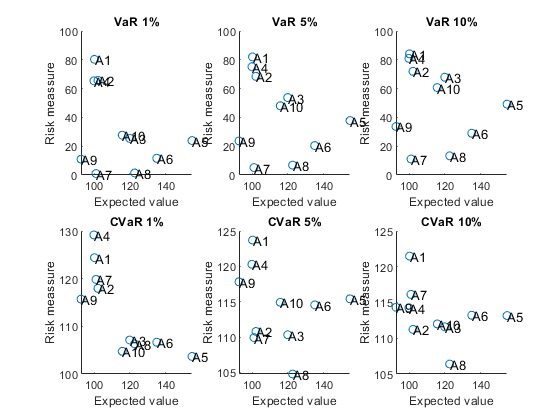


% d %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%labels for the scatter plots
labels = {'A1','A2','A3','A4','A5','A6','A7','A8','A9','A10'};

%subplot command is useful
% H = subplot(m,n,p), or subplot(mnp), breaks the Figure window
%     into an m-by-n matrix of small axes, selects the p-th axes for
%     the current plot, and returns the axes handle.

%you can uncomment and test the code below
% x = 0:0.01:2*pi;
% subplot(1,3,1)
% plot(x,sin(x))
% subplot(1,3,2)
% plot(x,cos(x))
% subplot(1,3,3)
% plot(x,tan(x))
% ylim([-5,5])
figure
subplot(2,3,1)
scatter(EV,Var1)
title('VaR 1%')
text(EV,Var1,labels, "SE")
xlabel('Expected value')
ylabel('Risk meassure')
subplot(2,3,2)
scatter(EV,Var5)
title('VaR 5%')
text(EV,Var5,labels, "SE")
xlabel('Expected value')
ylabel('Risk meassure')
subplot(2,3,3)
scatter(EV,Var10)
title('VaR 10%')
text(EV,Var10,labels, "SE")
xlabel('Expected value')
ylabel('Risk meassure')
subplot(2,3,4)
scatter(EV,CVar1)
title('CVaR 1%')
text(EV,CVar1,labels, "SE")
xlabel('Expected value')
ylabel('Risk meassure')
subplot(2,3,5)
scatter(EV,CVar5)
title('CVaR 5%')
text(EV,CVar5,labels, "SE")
xlabel('Expected value')
ylabel('Risk meassure')
subplot(2,3,6)
scatter(EV,CVar10)
title('CVaR 10%')
text(EV,CVar10,labels, "SE")
xlabel('Expected value')
ylabel('Risk meassure')


% g %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%first create a matrix that can contain the CVaR results for all the 10
%invesment oppportunities with 100 different alpha values
%then use for loop to calculate the 10*100 cases separately
Vars = zeros(10,100);
CVars = zeros(10,100);

for i = 1:10
    for j = 1:100
        Vars(i,j) = prctile(samples(i,:), j);
        TailIndices = find(samples(i,:)<=Vars(i,j));
        CVars(i,j) = mean(samples(i,TailIndices));
    end
end
%plot the CVaRs of each investment opportunity using alpha = 1:1:100
alpha = 1:1:100

alpha =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


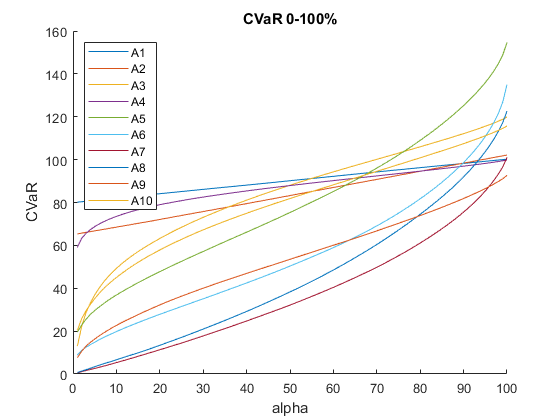

figure
hold on 
for i = 1:10
    plot(alpha, CVars(i,:))
end
title("CVaR 0-100%")
xlabel("alpha")
ylabel("CVaR")
legend('A1','A2','A3','A4','A5','A6','A7','A8','A9','A10', 'location','northwest')

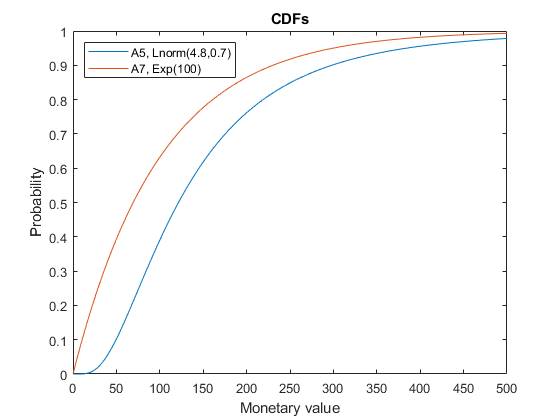


% h %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% previously we used function pdf(), there is a similar function for
% cumulative distibution functions
t2 = 0:1:500;
a5_cdf = cdf(pd5,t2);
a7_cdf = cdf(pd7,t2);
figure
plot(t2,a5_cdf)
hold on
plot(t2,a7_cdf)
title("CDFs")
ylabel("Probability")
xlabel('Monetary value')
legend('A5, Lnorm(4.8,0.7)', "A7, Exp(100)", 'location','northwest')